# Demo of BehaviorData

### Construct an instance of BehaviorData

Example: you just collected timestamps for mouse b16 on day 5 of testing

%behavioral parameters
behavior='conditioning';
CSplus='high tone'; %'lowTone' or 'highTone'
traceInterval=2; %seconds
duration=45*60; %45 minute session in seconds
load('time stamps for demo.mat')
obj=BehaviorData(stamps,16,5,behavior,CSplus,duration*1000,traceInterval);
saveObj(obj);

data for b16 conditioning 5 has been saved


### Simple graphs to get a sense of the data

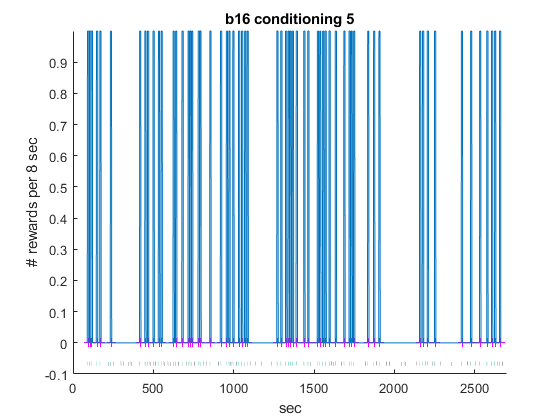

%the method uses a sliding window of 8 seconds
obj.plotWholeSession()

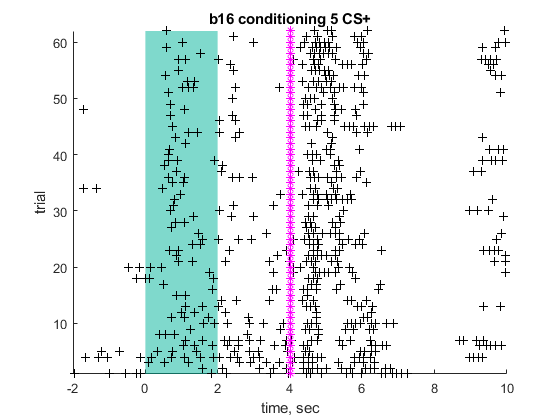

%show the licking data aligned to CS+ onset
obj.rasterPlot('CS+')

%if you saved the object with saveObj() then you can load it like so
load('b16 CSPF5.mat')

### Analyzing data from multiple mice or multiple sessions

Example: load the objects from day 10 of mice N36, N38, N39 and calculate the proportion of trials with anticipatory licking

sessionNum=10;
mouseIDs=[36 38 39];
hasN=true;
dataForAllMice=loadBehaviorData(mouseIDs,sessionNum,hasN);
results = dailyResults(dataForAllMice) %tabulate the results
%the last columns of the table contain the the proportion of trials with
%anticipatory licks for the CS+ and CS-

Example: add weight and pre-test eating data to objects created previously

names={'bN36 CSPF14','bN39 CSPF14'};
objArray=loadBehaviorData(names);
%refeeding volume
reVol=[3.3
4.2]; %mL, g, or kcal
W=[19.7 %weight on that day
18.6];
volForTest=[0.9
0.5];
%initial weight
initW=[22.5 
21.4];
% objArray=data; 
for i=1:length(objArray) %for each mouse
    data=objArray{i};
    data.feedingFlavor='vanilla';
    data.refeeding= reVol(i); %add the refeeding volume
    data.weight=W(i);
    data.initWeight=initW(i);
    data.volForTest=volForTest(i);
    saveObj(data) %save the file with the added information
end


### Is there more consumption for the CS+ compared to the CS-? Yes

cohort: b136-140 and 142, 6 mice

mouseIDs=[136:140 142];
cuedTests=loadBehaviorData(mouseIDs,54);

Data was successfully loaded.


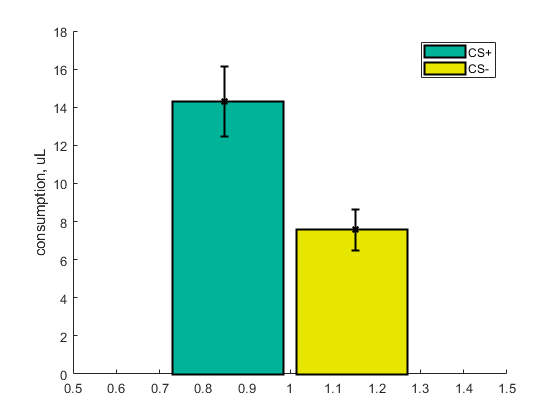

period=10000; %ms, 2 sec of CS and 8sec after
cellArray=cuedTests;
nSession=length(cellArray);
Vfixed=zeros(nSession,2); %CS+ and CS- columns
for i=1:nSession %for each session or mouse
    Vfixed(i,:)=volumePerCS(cellArray{i},period,true);
end
figure; hold on
%include error bars for SEM
barCS(1,Vfixed)
ylabel('consumption, uL')
legend('CS+','CS-')

%compare the CS+ and CS- consumption, use non-parametric test
p=ranksum(Vfixed(:,1),Vfixed(:,2))

p = 0.0260